% Model A

b1Rate = 3.5:0.25:7.5;
b2Rate = 9:0.5:17;
b3Rate = 3.5:0.25:7.5;

disp(['Increasing B1 Rate']);

Increasing B1 Rate


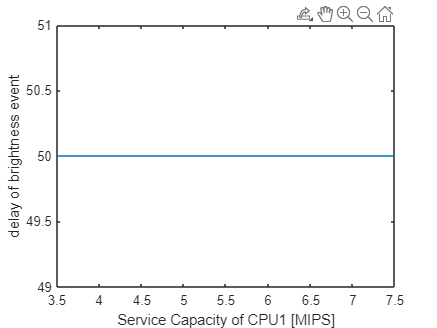

[delH, delN] = calculateDel(b1Rate,10,4);

plot(b1Rate,delH);
xlim([3.5,7.5]);
xlabel('Service Capacity of CPU1 [MIPS]');
ylabel('delay of brightness event');

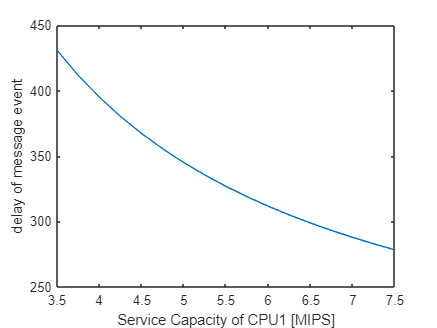


plot(b1Rate,delN);
xlim([3.5,7.5]);
xlabel('Service Capacity of CPU1 [MIPS]');
ylabel('delay of message event');


disp(['Increasing B2 Rate']);

Increasing B2 Rate


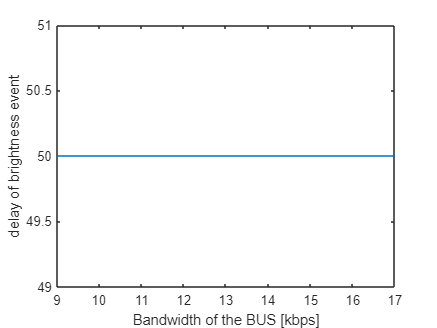

[delH, delN] = calculateDel(4,b2Rate,4);
plot(b2Rate,delH);
xlim([9,17]);
xlabel('Bandwidth of the BUS [kbps]');
ylabel('delay of brightness event');

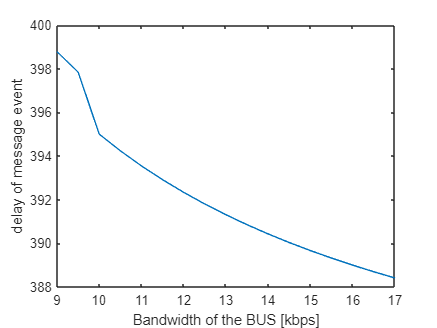


plot(b2Rate,delN);
xlim([9,17]);
xlabel('Bandwidth of the BUS [kbps]');
ylabel('delay of message event');


disp(['Increasing B3 Rate']);

Increasing B3 Rate


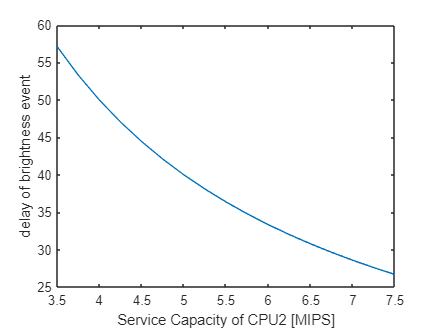

[delH, delN] = calculateDel(4,10,b3Rate);
plot(b3Rate,delH);
xlim([3.5,7.5]);
xlabel('Service Capacity of CPU2 [MIPS]');
ylabel('delay of brightness event');

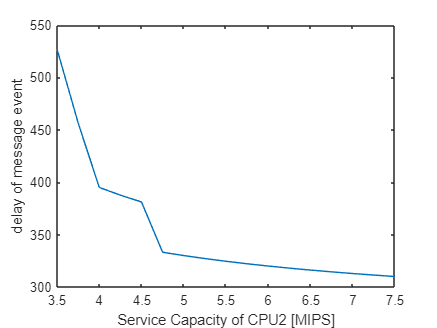


plot(b3Rate,delN);
xlim([3.5,7.5]);
xlabel('Service Capacity of CPU2 [MIPS]');
ylabel('delay of message event');

function [delH, delN] = calculateDel(b1Rate,b2Rate,b3Rate)
    aH_in = rtcpjd(66.7, 0, 0);
    aN_in = rtcpjd(1000, 0, 0);
    
    e1 = 200;
    e2 = 1000;
    e3 = 160;
    e4 = 100;

    for i=1:17
        if length(b3Rate) == 1
            b3_in = rtcfs(b3Rate);
            [~, b3_out1, del1, ~] = rtcgpc(aH_in, b3_in, e1);
        else
            b3_in = rtcfs(b3Rate(i));
            [~, b3_out1, del1, ~] = rtcgpc(aH_in, b3_in, e1);
        end

        if length(b1Rate) == 1
            b1_in = rtcfs(b1Rate);
            [aN_out1, ~, del2, ~] = rtcgpc(aN_in, b1_in, e2);
        else
            b1_in = rtcfs(b1Rate(i));
            [aN_out1, ~, del2, ~] = rtcgpc(aN_in, b1_in, e2);
        end

        if length(b2Rate) == 1
            b2_in = rtctdma(8,10,b2Rate);
            [aN_out2, ~, del3, ~] = rtcgpc(aN_out1, b2_in, e3);
        else
            b2_in = rtctdma(8,10,b2Rate(i));
            [aN_out2, ~, del3, ~] = rtcgpc(aN_out1, b2_in, e3);
        end

        [~, ~, del4, ~] = rtcgpc(aN_out2, b3_out1, e4);

        delH(i) = del1;
        delN(i) = del2 + del3 + del4;
    end
end